# Derivative Rules for Powers

The basic limit definition of the derivative can be slow and awkward to apply. For most standard functions, it is easier to prove a few rules for simple functions and then compute complicated derivatives by breaking the functions down into simple pieces that fit the known rules.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor window.

 Although the code is hidden, some interactivity requires familiarity with MATLAB syntax. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

 This script builds on the limit definition of the derivative, as discussed in [derivativeDefinition.mlx](matlab:open('./derivativeDefinition.mlx')).

## Power Rule

One simple function type is the power functions: $y = x^n$. The following section calculates the derivative of positive integer powers using the difference quotient. 

Recall that a linear function is presented in the standard form $y = mx+b$ where $m$ is the slope and $b$ is the $y$-intercept. Since slopes are derivatives, this means that the derivative of $y=mx+b$ must be $m$. Observe:

$\frac{dy}{dx} = \lim_{h\to 0} \frac{(m(x+h)+b)-(mx+b)}{h} = \lim_{h\to 0}\frac{(mx+mh+b)-(mx+b)}{h} = \lim_{h\to 0} \frac{mh}{h} = \lim_{h\to 0} m = m$.

This result remains true in the special case of a constant function with $m=0$ which is described by $y=b$. The power of calculus is in its ability to describe the slope of curves as well as straight lines. 

### Example: Derivative of a quadratic

Let $y(x) = x^2$. Applying the[ limit definition of the derivative](http://derivativedefinition.mlx), we calculate that


$$\frac{dy}{dx} = \lim_{h \to 0} \frac{y(x+h)-y(x)}{h}$$
        


$$\frac{dy}{dx} = \lim_{h\to 0} \frac{(x+h)^2-x^2}{h}$$
            


$$\frac{dy}{dx} = \lim_{h\to 0} \frac{(x^2+2xh+h^2)-x^2}{h}$$



$$\frac{dy}{dx} = \lim_{h\to 0} \frac{2xh+h^2}{h}$$
                 


$$\frac{dy}{dx} = \lim_{h\to 0} 2x+h$$
                    


$$\frac{dy}{dx} = 2x$$
                               

One way to check the derivative is to use it to graph the tangent line to the function at various points. Recall that the tangent line is the straight line through a given point on the graph, say $(a,f(a)) = (a, a^2)$ with the same slope, that is derivative, as the function itself at that point which is $f'(a) = 2a$. Given the derivative calculated above, we have a tangent line through $x=a$ of:


$$y = f(a) + f'(a)(x-a)$$
                                       

$y = a^2+2a(x-a)$   or, simplified    $y=2ax-a^2$

 Graphing the function and the tangent line to the function allows a quick visual check on the accuracy of the calculation of the derivative.               

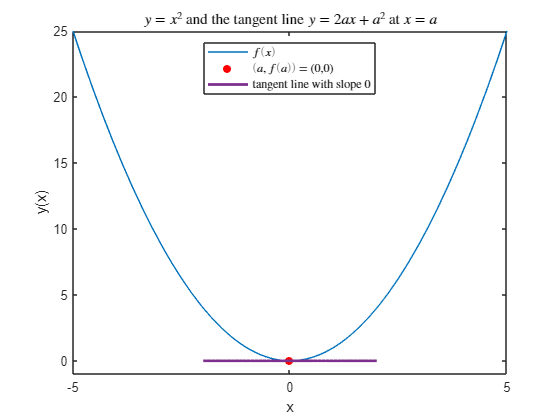

syms x         % Create a symbolic variable
f(x) = x^2;    % Define f(x) as a symbolic function
fplot(x^2)     % Symbolically plot y=x^2
ylim([-1 25])  % Extend the window of the plot to better see the apex of the graph
title("$y=x^2$ and the tangent line $y=2ax+a^2$ at $x=a$","Interpreter","latex")
xlabel("x")    % Label the x axis
ylabel("y(x)") % Label the y axis
a =0;        % Request user input to select a point 
 
hold on
ya = double(f(a));                    % Compute f(a) as a number 
scatter(a,ya,'r','filled')            % Add a point at (a,f(a))
[m,linApprox] = getLinApprox(f,x,a);  % The function getLinApprox is defined in Helper Functions
fplot(linApprox(x),[a - 2,a + 2],"Color",[0.4940 0.1840 0.5560],"LineWidth",2); % Purple
hold off
legend(["$f(x)$" "$(a,f(a))$ = ("+a+","+ya+")" "tangent line with slope "+m],"Location","north","Interpreter","latex")

  **Try. **Move the slider to different values and observe how the slope of the tangent line varies at different points. Does it match the algebraically computed value?

** Exercise 1**. Using the limit definition of the derivative, calculate the derivative $\frac{dy}{dx$ for $y(x) = x^3$.

  **Pro-tip**. MATLAB syntax is 7`*x^2` for $7x^2$ or `exp(-2*x)` for $e^{-2x}$. For more detail, check out the Help Center documentation for [mathematical functions](https://www.mathworks.com/help/matlab/referencelist.html?type=function&listtype=cat&category=mathematics) or the [Basic Functions Reference](https://www.mathworks.com/content/dam/mathworks/fact-sheet/matlab-basic-functions-reference.pdf).

syms x
myAnswer = 1* x^3;
 
disp("My answer is:")
displayFormula("dy/dx = myAnswer")
checkEx1(myAnswer)

### Identifying the Power Rule

The computations involved in calculating the derivative of a power from the limit definition of the derivative get more involved quickly as the power gets larger. This section implements the same computations you worked through above to allow testing several powers easily to search for patterns in the results.

  **Try. **Choose a power of $n$ to run the calculations below to calculate the derivative $\frac{d}{dx}\left[x^n\right]$:

clear
syms x h                       % Define symbolic variables
                % Run this section
n = 6  % Select the desired positive integer power

n = 6

f(x) = x^n;                    % Define a symbolic function f(x) = x^n
oldPrefs = sympref();          % Save the current user preferences to reset at the end of the section
sympref('PolynomialDisplayStyle', 'descend');  % Present polynomials in descending power format
sympref('FloatingPointOutput',false);          % Do not use floating point representations
fxhD = f(x+h);                 % Name the symbolic function f(x+h)

Evaluate:

displayFormula("f(x+h) = fxhD") % Display the formula

$$f\left(x+h\right)={\left(x+h\right)}^{6}$$

% Use the built-in Taylor polynomial approximation to expand the polynomial 
fxph(x,h) = taylor(f(x+h),x, "ExpansionPoint",0, "Order", 11);
fxphD = fxph(x,h);                    % Name the symbolic function
displayFormula("f(x+h) = fxphD")      % Display the formula

$$f\left(x+h\right)=x^{6}+6\,h\,x^{5}+15\,h^{2}\,x^{4}+20\,h^{3}\,x^{3}+15\,h^{4}\,x^{2}+6\,h^{5}\,x+h^{6}$$

Calculate the difference quotient:

DQ = (fxph - f(x))/h;                  % Name the symbolic difference quotient
displayFormula("(f(x+h)-f(x))/h = DQ") % Display the formula

$$\frac{f\left(x+h\right)-f\left(x\right)}{h}=\frac{6\,h\,x^{5}+15\,h^{2}\,x^{4}+20\,h^{3}\,x^{3}+15\,h^{4}\,x^{2}+6\,h^{5}\,x+h^{6}}{h}$$

Simplify the difference quotient:

DQsimplified = simplify(DQ(x,h));      % Name the simplified symbolic difference quotient
displayFormula("(f(x+h)-f(x))/h = DQsimplified") % Display the formula

$$\frac{f\left(x+h\right)-f\left(x\right)}{h}=6\,x^{5}+15\,h\,x^{4}+20\,h^{2}\,x^{3}+15\,h^{3}\,x^{2}+6\,h^{4}\,x+h^{5}$$

Compute the limit of the difference quotient as $h$ approaches 0:

displayFormula("df/dx = limit((f(x+h)-f(x))/h,h,0)")

$$\frac{\mathrm{df}}{\mathrm{dx}}=\lim_{h\to 0}\frac{f\left(x+h\right)-f\left(x\right)}{h}$$

displayFormula("df/dx = limit(DQsimplified,h,0)")

$$\frac{\mathrm{df}}{\mathrm{dx}}=\lim_{h\to 0}6\,x^{5}+15\,h\,x^{4}+20\,h^{2}\,x^{3}+15\,h^{3}\,x^{2}+6\,h^{4}\,x+h^{5}$$

limDQ = limit(simplify((f(x+h)-f(x))/h),h,0);  % Name the limit of the simplified difference quotient
displayFormula("df/dx = limDQ")                % Display the resulting formula

$$\frac{\mathrm{df}}{\mathrm{dx}}=6\,x^{5}$$

sympref(oldPrefs);   % Restore the system preferences you had before running this script.

 **Reflect **Can you find a pattern in the results $\frac{df}{dx}$ for different values of $n$?

** Exercise 2**. For a positive integer $n$, can you write down a rule for the derivative?

If $f(x) = x^n$, then $\frac{df}{dx}$ = ? 

syms x n                      % Define symbolic variables
dfdx =  x^n;  % Assign a user-defined function to dfdx
checkPwrRule(dfdx);           % checkPwrRule is defined in Helper Functions
% checkPwrRule compares dfdx to the correct power rule and displays
% feedback
                   % Run this section

### Extending the Power Rule

What happens if $n$ is not a positive integer? If $n=0$ this is quite doable by hand, but what happens with other values? Does your rule still work?

syms x h                                      % Define symbolic variables
oldPrefs = sympref();                         % Save current preferences for restoration at the end of the section
sympref('PolynomialDisplayStyle', 'descend'); % Present polynomials in descending power format
sympref('FloatingPointOutput',false);         % Do not use floating point representations
n = 0.5                      % Select a power n

n = 0.5000

order = 5             % Select an order to use in the Taylor approximation

order = 5

                                % Run this section
f(x) = x^n                                    % Define a symbolic function f(x) = x^n

$$f(x) = \sqrt{x}$$

fxph(x,h) = f(x+h);                           % Create a multivariable function to use in the Taylor expansion
% The definition of DQ uses simplify on the difference quotient to
% eliminate the common factors in the rational expression and expand to
% split into recognizable terms
DQ = expand(simplify((taylor(fxph,h,"Order",order)-f(x))/h));
displayFormula("f(x+h) = DQ")

$$f\left(x+h\right)=\frac{1}{2\,\sqrt{x}}-\frac{h}{8\,x^{3/2}}+\frac{h^{2}}{16\,x^{5/2}}-\frac{5\,h^{3}}{128\,x^{7/2}}$$

displayFormula("df/dx = limit((f(x+h)-f(x))/h,h,0)") % Display the formula

$$\frac{\mathrm{df}}{\mathrm{dx}}=\lim_{h\to 0}\frac{f\left(x+h\right)-f\left(x\right)}{h}$$

DQ0 = DQ(x,0);                                      % Name the difference quotient evaluated
displayFormula("df/dx = limit(DQ,h,0)")

$$\frac{\mathrm{df}}{\mathrm{dx}}=\lim_{h\to 0}\frac{1}{2\,\sqrt{x}}-\frac{h}{8\,x^{3/2}}+\frac{h^{2}}{16\,x^{5/2}}-\frac{5\,h^{3}}{128\,x^{7/2}}$$

displayFormula("df/dx = DQ0")

$$\frac{\mathrm{df}}{\mathrm{dx}}=\frac{1}{2\,\sqrt{x}}$$

sympref(oldPrefs);   % Restore the system preferences you had before running this script.

  **Pro-tip**. The method used to approximate the difference quotient here is called a [Taylor Series](https://www.mathworks.com/help/symbolic/sym.taylor.html#busozb7-8). This is an extremely useful method you are likely to see again. The higher the order the closer the approximation is to your original function. What impact does changing the order have on your calculation?

** Exercise 3.**

Compute the derivative of the following expressions by hand using the Power Rule:

- 
$$x^2$$
 

- 
$$x^{-2}$$


- 
$$x^{1/2$$


- 
$$3$$


pwrRuleChecked = false;     % This sets a boolean to control showing/hiding the solutions
if pwrRuleChecked
    syms x; %#ok<*UNRCH> 
    disp("1. ")
    ans1 = 2*x
    disp("2. ")
    ans2 = -2*x
    disp("3. ")
    ans3 = 1/2*x^(-1/2)
    disp("4. ")
    ans4 = 0
    disp("Note: This can be thought of as a power rule in terms of x^0, but it is sometimes called the Constant Rule.")
    disp("      The derivative of any constant is zero!")
end

## Linearity Rules

The trouble with the power rule is that it is very limited in scope. It only applies to the derivatives of $x^n$. Functions of the form $x^n$ are called monic (coefficient is 1) monomials (there is only one term in the expression). Most applications of powers result in polynomial functions such as $T(x) = \frac{9}{5}x+32$ or non-monic monimal such as $G(x) = 2.365x^{-2}$. Neither of these functions can be differentiated by applying to power rule directly. We can extend our reach to the entire set of polynomials by checking how derivatives interact with multiplication by constants and with addition. Happily, the conclusion is that we can multiply by a constant before or after computing a derivative and reach the same result. Similarly, the derivative of a sum is the sum of the derivatives. What does this look like in derivative notation?

Remember that we called the [derivative an operator](http://derivativedefinition.mlx). In fact, it is a linear operator, which means that it satisfies the following conditions for any differentiable functions $f(x)$ and $g(x)$ and any constant $c$:


$$\frac{d}{dx}\left[f(x)+g(x)\right] = \frac{d}{dx}\left[f(x)\right] + \frac{d}{dx}\left[g(x)\right] = \frac{df}{dx} + \frac{dg}{dx}$$



$$\frac{d}{dx}\left[cf(x)\right] = c\left(\frac{d}{dx}\left[f(x)\right]\right) = c\frac{df}{dx}$$


Let's start from the limit definition of the derivative and see why the derivative satisfies these conditions.

### Sums and Differences


$$\frac{d}{dx}\left[f(x)+g(x)\right] = \lim_{h\to 0} \frac{(f(x+h)+g(x+h)) - (f(x)+g(x))}{h}$$



$$\frac{d}{dx}\left[f(x)+g(x)\right] = \lim_{h\to 0} \frac{f(x+h)-f(x)+g(x+h)-g(x)}{h}$$
      


$$\frac{d}{dx}\left[f(x)+g(x)\right] = \lim_{h\to 0}\frac{f(x+h)-f(x)}{h} + \lim_{h\to 0}\frac{g(x+h)-g(x)}{h}$$



$$\frac{d}{dx}\left[f(x)+g(x)] = \frac{d}{dx}[f(x)] + \frac{d}{dx}[g(x)] = \frac{df}{dx}+\frac{dg}{dx}$$
                 

### Multiplying by Constants


$$\frac{d}{dx}\left[cf(x)\right] = \lim_{h\to 0} \frac{cf(x+h)-cf(x)}{h}$$
          


$$\frac{d}{dx}\left[cf(x)\right] = \lim_{h\to 0} c\left(\frac{f(x+h)-f(x)}{h}\right)$$
      


$$\frac{d}{dx}\left[cf(x)\right] = c\lim_{h\to 0}\frac{f(x+h)-f(x)}{h} = c\frac{df}{dx}$$


** Exercise 4**. Calculate the derivative with respect to $x$ for each of the following:

- 
$$x^2+x^3$$


- 
$$x^{-2}-x^4$$


- 
$$x^{1/2}+x^{-1/2}$$


- 
$$\frac{2}{3}x^3 + 6$$
 

- 
$$7x^3-12x^2+3x-8$$


linearityChecked = false;    % This sets a boolean to control showing/hiding the solutions
if linearityChecked
    syms x;
    disp("1.")
    disp(2*x + 3*x^2)
    disp("2.")
    disp(-2*x^(-1) - 4*x^3)
    disp("3.")
    disp(1/2 * x^(-1/2) - 1/2 * x^(-3/2))
    disp("4.")
    disp(2*x^2 + 0)
    disp("5.")
    disp(21*x^2-24*x+3)
end

 **Reflect**

- Is there a pattern to the graphs of the powers and their derivatives? 

- If you know something about how a function is changing, what can you say about the original function? 

- Where does a polynomial function reach a maximum or minimum value? Does this have any relationship to its derivative?

### Application: Parabolic Motion

A standard problem in the history of calculus (and physics) is the description of parabolic motion. Using a bit of imagination, consider an object that is impervious to heat, cold, and pressure such that it could be tested on any of the bodies in our solar system. 

  **Try **Choose some values and begin. 

planet = "Earth";     % Choose a planet, moon, or star
g = getGravity(planet);            % getGravity is defined in Helper Functions
% getGravity sets the acceleration constant g based on the solar system
% body chosen, then print the acceleration selected
disp("On " + planet + " the acceleration due to gravity is " + g + "m/s^2.")
v0 = 10;         % User selection for the initial velocity   
h0 = 1.88;         % User selection for the initial height
syms t;                            % Create a symbolic variable 
                       % Run this section
[fh, tmax] = solveParabolicMotion(planet,v0,h0);  % solveParabolicMotion is defined in Helper Functions
% solveParabolicMotion sets up and graphs a parabola

Once you have chosen your preferred location and set up your trajectory, let's use calculus to study the motion. We have already established that the height of our object is given by $h(t) = -\frac{g}{2}t^2+v_0t+h_0$. The velocity of our object is given by $v(t) = \frac{d}{dt}[h(t)]$. You may use either numbers or the variables `g`, `v0`, and `h0` as well as the independent variable `t` to express your result.

if exist("planet","var")          % Check for planet to see if the previous section has been run
v = @(t) -g*t^2/2+v0*t+h0;    % User-defined anonymous function of t
checkVelocity(v,fh)               % checkVelocity is defined in Helper Functions

else                      % If "planet" doesn't exist, warn the user to run the previous section
    warning("You must choose a solar system body and graph the resulting parabola to continue.")
end
                % Run the section

Thinking about what you know about derivatives, what is the velocity at the apex of the parabola?

apexVelocity = "unknown";  % user-selected string value from options
checkApexVelocity(apexVelocity);  % checkApexVelocity is defined in Helper Functions
% checkApexVelocity determines if the argument identifies the sign of the
% derivative at the apex of a parabola and gives feedback

Can you solve for the point at which the apex of the parabola is achieved? 

if exist("planet","var")              % Check for planet to see if the setup section has been run
    tApex =  0;     % User-defined time value for the apex of the parabola
    hApex =  h0;     % User-defined height value for the apex of the parabola
    checkApex(tApex,hApex,g,v0,h0);   % checkApex is defined in Helper Functions
    % checkApex determines if (tGuess,hGuess) is the correct apex point for a
    % parabola h(t) = -g/2*t^2+v0*t+h0
else         % If "planet" doesn't exist, warn the user to run the setup section
    warning("You must choose a solar system body and graph the resulting parabola to continue.")
end
   % Run this section


## Practice Computing Derivatives Using the Power and Linearity Rules

** Practice.**

                                  % Run this section
clear                                           % Clear variables
varOpts = ["t" "r" "x" "z"];                    % Define the list of variables to use in the problems
[myFun,varChoice,varStr] = genProb(varOpts,"power");   % genProb is defined in Helper Functions
% genProb chooses a variable from varOpts and generates a power rule 
% derivative problem of a randomized function

if exist("myFun","var")                        % Check that a problem has been generated
    syms t r x z C                              % Set up the relevant symbolic variables
    myAnswer = r;            % User-defined solution
    check(myFun,varChoice,myAnswer);            % check is defined in Helper Functions
    % check generates correct answers by differentiating and provides both
    % feedback and the correct solution
else                                            % If there is no generated problem, warn the user
    warning("You must generate a problem before you can check a solution.")
end
                                 % Run this section

## Helper Functions

If you wish to see the details of the code, select the **View** tab on the MATLAB toolstrip and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor window.

function [m,linApprox] = getLinApprox(y,x,a)
% getLinApprox creates a tangent line function to y(x) at the point x=a
%
% getLinApprox requires four arguments
%   y a symbolic function
%   x the independent variable
%   a the point of tangency
% getLinApprox returns two values
%   m is the slope as a double
%   linApprox is the tangent line to y(x) at x=a as a symfun
dy = diff(y,x);         % Symbolically compute the derivative y'(x)
m = subs(dy,x,a);       % Symbolically compute the slope m = y'(a)
ya = subs(y,x,a);       % Symbolically compute y(a)
linApprox = @(x) ya+m*(x-a);  % Symbolically compute the tangent line y = y(a) + y'(a)*(x-a)
m = double(m);          % Express the slope as a number
end

function checkEx1(myAnswer)
% checkEx1 checks the expression for the derivative of y=x^3
syms x
correctAnswer = 3*x^2;
if myAnswer == correctAnswer
    disp("That is correct.")
else
    disp("That is incorrect. Please try again.")
end
end

function g = getGravity(planet)
% getGravity sets the acceleration constant g based on the solar system
% body chosen
%
% planet is a string
switch planet
    case "Mercury"
        g = 3.59;
    case "Venus"
        g = 8.87;
    case "Earth"
        g = 9.81;
    case "Mars"
        g = 3.71;
    case "Jupiter"
        g = 25.95;
    case "Moon"
        g = 1.62;
    case "Saturn"
        g = 11.08;
    case "Neptune"
        g = 14.07;
    case "Uranus"
        g = 10.67;
    case "Pluto"
        g = .62;
    case "Sun"
        g = 274.13;
end
end

function [fh, tmax] = solveParabolicMotion(planet,v0,h0)
% solveParabolicMotion sets up and graphs a parabola
%
% Inputs: planet is a string, v0 = initial velocity, h0 = initial height
% Outputs: fh is a handle to the parabolic equation, [0 tmax] is the xlims of
% the plot
syms t                             % Create a symbolic variable t
g = getGravity(planet);            % getGravity is defined in Helper Functions
% getGravity sets the acceleration constant g based on the solar system
% body chosen
fh = @(t)-g*t.^2/2 + v0*t+h0;      % Define a function handle for the parabola
if v0 < 0 && h0 < 0                % Check for reasonable initial values
    disp("You have to throw upwards, and be above the ground, or the ball won't travel anywhere!")
    disp("Please set positive v0 and h0 values and run this again.")
elseif v0 < 0                      % Check for reasonable initial values
    disp("We would like to study parabolic motion with an apex.")
    disp("Please set a positive value of v0 and run this again.")
end
% Compute the physically interesting value of tmax
if h0 > 0                          
    % For positive initial height, select the most positive root of the
    % parabola -g/2*t^2+v0*t+h0
    tmax = max(roots([-g/2,v0,h0])); %#ok<*NASGU> 
else
    % For non-positive initial height, set a tmax that centers the apex if v0>0
    % This returns to the starting height at tmax
    % If v0<0, there are no physically realistic choices so the user is
    % encouraged to choose different initial values
    tmax = abs(2*v0/g);
end
fplot(fh,[0 tmax])                           % Symbolically plot the parabola
formatSpec = "$h(t) = %.2ft^2+%.2ft+%.2f$";  % Set up a format string for displaying 
                                             % information on the graph to 2 decimal places 
hStr = compose(formatSpec,[-g/2 v0 h0]);     % Create the string with current values
% Label the plot appropriately
legend(hStr,"Interpreter","latex","Location","best")
title("Parabolic Motion on "+planet)
xlabel("Time (s)")
ylabel("Elevation (m)")
end

function checkVelocity(vh,fh)
% checkVelocity determines whether the first argument is the derivative of
% the second argument
%
% checkVelocity takes two function handles as arguments
syms t                   % Define a symbolic variable 
v(t) = vh(t);            % Create a symbolic function from the function handle
f(t) = fh(t);            % Create a symbolic function from the function handle
df(t) = diff(f,t);       % Compute the symbolic derivative as a function
if isequal(v,df)         % Check whether v is the derivative of f
    disp("Correct.")
else                     % If the answer is incorrect, try to give useful feedback
    % Identify the coefficients of the solution
    correctG = double(diff(f,t,2));       
    correctV0 = double(df(0));
    % Check whether the answer v(t) was a linear function, i.e. with
    % constant derivative. If not, warn the user it should be linear
    try answerG = double(diff(v,t));
    catch
        warning("The derivative should be a linear function.")
        answerG = 0;
    end
    % Check whether each each term was correct and give feedback
    answerV0 = vh(0);
    if isequal(correctG,answerG)
        disp("You made a mistake with the constant term.")
        disp("Please check your work and resubmit.")
    elseif isequal(correctV0,answerV0)
        disp("You made a mistake with the linear term.")
        disp("Please check your work and resubmit.")
    else
        disp("Please review the rules for computing derivatives of polynomials.")
        disp("Then fix the answer and resubmit.")
    end
end
end

function checkApexVelocity(str)
% checkApexVelocity determines if the argument identifies the sign of the
% derivative at the apex of a parabola and gives feedback
if str == "zero"
    disp("Correct!")
else
    disp("That is not correct. Please review what you know about graphical derivatives and try again.")
end
end

function checkApex(tGuess,hGuess,g,v0,h0)
% checkApex determines if (tGuess,hGuess) is the correct apex point for a
% parabola h(t) = -g/2*t^2+v0*t+h0
syms t                                    % Define a symbolic variable
fh = @(t) -g/2*t.^2+v0*t+h0;               % Define the parabola as a function handle
if tGuess == v0/g && hGuess == fh(v0/g)   % Check for correctness, and give feedback
    disp("Correct.")
    disp("Note: As a theme in calculus, you can replace some of the specific formulas you memorized")
    disp("      in the past with general rules from calculus that allow you to quickly compute solutions.")
% For incorrect solutions, try to determine how the answer is wrong and provide appropriate feedback    
elseif tGuess == v0/g && hGuess ~= fh(v0/g)  % Correct time, incorrect height
    disp("You have the correct time, but the incorrect height.")
    disp("How can you evaluate the height at a given time?")
    disp("Please check your work and resubmit your solutions.")
elseif tGuess ~= v0/g && hGuess == fh(v0/g)  % Correct height, incorrect time
    disp("You have the correct maximal height, but the incorrect time.")
    disp("Remember that the velocity is zero at the apex. How can you use that to find the time?")
    disp("Please check your work and resubmit your solutions.")
else                                         % No correct components, offer hints and suggestions
    disp("Your answers are incorrect. Please note that they need to be exact values so it may be easiest to work in terms of g, v0, and h0.")
    disp("Remember that the velocity is zero at the apex. How can you use that to find the time?")
    disp("Once you know the time, how can you find the height at that time?")
    disp("Please check your work and resubmit your solutions.")
end
tmax = double(abs(v0/g*2));  % Set a window to see the full parabola when v0>0
fplot(fh, [0, tmax])         % Symbolically plot the parabola in that window
ax = gca;                    % Define an axes handle
yLimits = ax.YLim;           % Extract the y limits of the window 
% Increase the upper y limit so that the apex is clearly visible in the plot
yLimits(2) = .1*(yLimits(2)-yLimits(1))+yLimits(2);  
ax.YLim = yLimits;           % Set the y limits on the axes
hold on
xline(tGuess, "r--")         % Add a vertical line at the user-defined tGuess
yline(hGuess, "g:")          % Add a horizontal line at the user-defined hGuess
% Label the plot appropriately
title("Locating the Apex of a Parabola")
xlabel("t (s)")
ylabel("h (m)")
legend("Parabola", "My Calculated Apex Time", "My Calculated Apex Height", "Location","best")
hold off
end

function checkPwrRule(dfdx)
% checkPwrRule compares dfdx to the correct power rule and displays
% feedback 
syms x n                           % Define symbolic variables x and n
pwrRule = n*x^(n-1);               % Define the power rule in terms of x and n
correct = isequal(dfdx,pwrRule);   % Check whether dfdx is equal to pwrRule
if correct                         % correct = 1, display "correct" feedback
    disp("Good work! The power rule is f'(x) = n*x^(n-1).")
else                               % correct = 0, display "incorrect" feedback
    disp("No, that isn't correct. Please try again.")
end
end


function [myFun,varChoice,varStr] = genProb(varOpts,probType)
% genProb chooses a variable from varOpts and generates a power rule 
% derivative problem of a randomized function
%
% Inputs: varOpts is an array of possible variables
%         probType is a string that identifies the function type
% Outputs: myFun is a symbolic function
%          varChoice is the independent variable as a symbolic variable
%          varStr is the independent variable as a string
varIdx = randi([1 length(varOpts)], 1);   % Randomly and uniformly select an element of varOpts
varStr = varOpts(varIdx);                 % Identify the string corresponding to that variable
varChoice = str2sym(varStr);              % Create a symbolic variable from varStr
a = 0;                                    % Initialize a
b = 0;                                    % Initialize b
% Create string instructions for the problem with reference to the chosen
% variable varStr
formatLine1 = "Take the derivative with respect to %s";
formatLine2 = "of the function f(%s) = ";
line1Str = compose(formatLine1,varStr);
line2Str = compose(formatLine2,varStr);
% This is structured to allow for additional types of derivative problems
% as seen in derivativeRulesCombinations, the switch is not actually
% necessary in this function as written
switch probType
    case "power" % Simple derivative
        myFun = genFunDiff(varChoice,[1, 10],"power");  % genFunDiff is defined in Helper Functions
        % genFunDiff generates a random function with a simple derivative
        % Then display the problem and generated function
        disp(line1Str)   
        disp(line2Str)
        disp(myFun)
end
end

function myFun = genFunDiff(var,bds,fType)
% genFunDiff generates a random function with a simple derivative
%
% Inputs: var is the independent variable
%         bds is a 1x2 vector of increasing integer values that set
%             the range for the coefficients
%         fType is an integer that identifies the type of function
% Outputs: myFun is the generated symbolic function
syms f(t)                       % Define a symbolic function
% Select 5 integers randomly and uniformly from the range bds 
params = randi(bds,[1,5]);      
% Select three booleans randomly and uniformly to define signs
% for the parameters
sgn1 = randi([0 1],1);          
sgn2 = randi([0 1],1);
sgn3 = randi([0 1],1);
% In this script fType = "power", but this function can be called to 
% generate other types of functions as well
if fType == "power"
    type = randi([1 4],1);  % Randomly choose one of four basic shapes
elseif fType == "exponential"
    type = 5;
elseif fType == "ln"
    type = 6;
elseif fType == "sinusoid"
    type = randi([7 8],1);
else
    type = randi([1 8],1);
end
% Set up parameter values using the random values generated above
a = (-1)^sgn1*params(1);
b = (-1)^sgn2*params(2);
c = max(params(3),params(5));
d = (-1)^sgn3*params(4);
e = params(3);

% Create a function of shape "type" with the chosen parameters
switch type
    case 1
        f(t) = a*t^(b);
    case 2
        f(t) = a*t^(b/c);
    case 3
        f(t) = a*t^(b)+c*t^(d);
    case 4
        f(t) = a*t^(b/c)+d*t^(e);
    case 5
        f(t) = a*exp(b*t);
        disp("Remember that exp(x) is the notation for e^x in MATLAB.")
    case 6
        f(t) = a*log(abs(b)*t);
        disp("Remember that log(x) is the notation for a natural logarithm in MATLAB.")
    case 7
        f(t) = a*sin(b*t+d);
    case 8
        f(t) = a*cos(b*t+d);
end

% Return the randomly generated function of the appropriate variable
myFun = f(var);
end

function correctAnswer = check(myFunc,myVar,myAnswer)
% check generates correct answers by differentiating and provides both
% feedback and the correct solution
%
% Inputs: myFunc is the symbolic function to differentiate
%         myVar is the independent variable
%         myAnswer is the symbolic test function
% Output: correctAnswer is a symbolic function that is the
%         derivative of myFunc with respect to myVar
correctAnswer = diff(myFunc,myVar);      % Symbolically calculate the derivative 
disp("When simplified, my answer is: ")  % Display the user's answer in simplified form
myAnswer %#ok<NOPRT> 
if correctAnswer == myAnswer             % Display feedback
    disp("My answer is correct.")
else                                     % If incorrect, include the correct answer in the feedback
    disp("My answer is incorrect. The correct answer is:");
    correctAnswer %#ok<NOPRT> 
    disp("Please try again with a new problem.")
end
end
